# Introduction to Synthetic Aperture Radar Using Python and MATLAB

## by Andy Harrison - © 2022 Artech House

### Example 2.12.7 Stripmap Clutter-to-Noise Ratio

## Calculate the clutter-to-noise ratio 

$\textrm{CNR}=\frac{P_{\textrm{avg}} A_e^2 \sigma_{0\;} \delta_{r\;} \;}{8\pi \lambda \;r^3 {v\;k\;T}_0 F\;L}$    Equation (2.26)

% Clear the workspace
clear

% Range resolution (m)
range_resolution = 25;

% Backscatter coefficient
backscatter_coefficient = [0.01, 0.05, 0.25];

% Average transmitted power (W)
average_power = 500;

% Antenna effective aperture (m^2)
effective_aperture = 1;

% Operating frequency (Hz)
operating_frequency = 3e9;

% Slant range (m)
slant_range = 100e3;

% System temperature (K)
system_temperature = 290;

% Noise figure (dB)
noise_figure = 9;

% Losses (dB)
losses = 12;

% Velocity (m/s)
velocity = linspace(25, 300, 1e3);

% Calculate the clutter-to-noise ratio
for i = 1:length(backscatter_coefficient)
    cnr(i,:) = stripmap_cnr(average_power, effective_aperture, backscatter_coefficient(i), range_resolution, ...
        operating_frequency, slant_range, velocity, system_temperature, noise_figure, losses);
end

## Plot the results

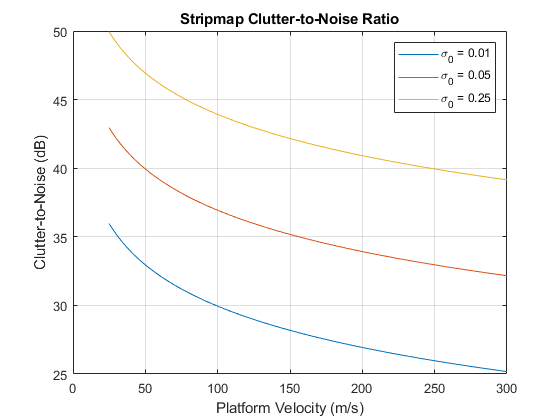

figure;
plot(velocity, db(cnr));
xlabel('Platform Velocity (m/s)')
ylabel('Clutter-to-Noise (dB)');
title('Stripmap Clutter-to-Noise Ratio')
grid on
legend('\sigma_0 = 0.01','\sigma_0 = 0.05', '\sigma_0 = 0.25')